syms x y z1 z2 z3%x代表acumulator，y代表cell
pbuyL=-0.4777;
pbuyH=-0.9897;
pbuyVH=-1.2877;
psell=0.7977;
R2=0.33;R3=0.27;R4=0.40;
X=[1:1:20];
Y=[1:1:30];
cel=xlsread('C:\Users\dell\Desktop\JK\second\2018-8-23-calculate.xlsx',1,'D3:D27')*100;
acc=xlsread('C:\Users\dell\Desktop\JK\second\2018-8-23-calculate.xlsx',1,'B3:B27')*33;%可以乘充放电比例
M=ones(length(X),length(Y));
N=ones(length(X),length(Y));
for k=1:1:length(Y)
    y=Y(k);
    for j=1:1:length(X)
        x=X(j);
        temp=0;
        z=0;
        for i=1:1:25
            a=99;
            b=29.7-y*R2*cel(i);
            c=19.8-y*R3*cel(i);
            d=59.4-y*R4*cel(i);
            e=19.8;
            f=9.9;
            ty=y*cel(i);
            tx=x*acc(i);
            if ty<=198/27
                if tx>d+e+f
                    z1=(a+b+c+d+e+f)*pbuyL;%
                elseif tx<=b
                    if tx<=e
                        z1=(e-tx)*pbuyVH+(d+f)*pbuyH+(a+c+2*tx)*pbuyL+(b-tx)*pbuyH;
                    else
                        z1=(d+e+f-tx)*pbuyH+(2*tx+a+c)*pbuyL+(b-tx)*pbuyH;
                    end%
                elseif tx<=d+e+f&&tx>b
                    if tx<=e
                        z1=(e-tx)*pbuyVH+(d+f)*pbuyH+(a+b+c+2*tx)*pbuyL;
                    else
                        z1=(d+e+f-tx)*pbuyH+(2*tx+a+b+c)*pbuyL;
                    end%
                end
            end%%1
            
            if ty>148.5
                if tx>-(b+c+d)&&tx>(e+f+a)
                    if ty<=237.6
                        z1=(a+b+c+d+e+f)*pbuyL;
                    else
                        z1=psell*-(a+b+c+d+e+f);
                    end%
                elseif tx<=-(b+c+d)&&tx>(e+f+a)
                    z1=psell*-(a+b+c+d+e+f);%
                elseif tx>-(b+c+d)&&tx<=(e+f+a)
                    if tx<=e
                        z1=(tx+b+c+d)*pbuyL+(e-tx)*pbuyVH+f*pbuyH+a*pbuyL;
                    elseif tx<=e+f&&tx>e
                        z1=(tx+b+c+d)*pbuyL+(e+f-tx)*pbuyH+a*pbuyL;
                    elseif tx>e+f
                        z1=(tx+b+c+d)*pbuyL+(e+f+a-tx)*pbuyL;
                    end%
                elseif tx<=-(b+c+d)&&tx<=(e+f+a)
                    if tx<=e
                        z1=-(tx+b+c+d)*psell+(e-tx)*pbuyVH+f*pbuyH+a*pbuyL;
                    elseif tx<=e+f&&tx>e
                        z1=-(tx+b+c+d)*psell+(e+f-tx)*pbuyH+a*pbuyL;
                    elseif tx>e+f
                        z1=-(tx+b+c+d)*psell+(e+f+a-tx)*pbuyL;
                    end% 
                end%
            end%%2

            if ty<=148.5&&ty>90
                if tx>-(b+c)&&tx>(d+e+f+a)
                        z1=-(a+b+c+d+e+f)*pbuyL;
                elseif tx>-(b+c)&&tx<=(d+e+f+a)
                    if tx<=e
                        z1=(tx+b+c)*pbuyL+(e-tx)*pbuyVH+(d+f)*pbuyH+a*pbuyL;
                    elseif tx<=d+e+f&&tx>e
                        z1=(tx+b+c)*pbuyL+(d+e+f-tx)*pbuyH+a*pbuyL;
                    elseif tx>d+e+f
                        z1=(tx+b+c)*pbuyL+(d+e+f+a-tx)*pbuyL;
                    end%
                elseif tx<=-(b+c)&&tx<=(d+e+f+a)
                    if tx<=e
                        z1=-(tx+b+c)*psell+(e-tx)*pbuyVH+(d+f)*pbuyH+a*pbuyL;
                    elseif tx<=e+f&&tx>e
                        z1=-(tx+b+c)*psell+(d+e+f-tx)*pbuyH+a*pbuyL;
                    elseif tx>e+f
                        z1=-(tx+b+c)*psell+(d+e+f+a-tx)*pbuyL;
                    end%
                end
            end%%3
            
            if ty<=90&&ty>198/27
                if tx>-(c)&&tx>(d+e+f+a+b)
                        z1=(a+b+c+d+e+f)*pbuyL;
                elseif tx>-(c)&&tx<=(d+e+f+a+b)
                    if tx<=b
                        z1=(tx+c)*pbuyL+(e-tx)*pbuyVH+(d+f)*pbuyH+(a+tx)*pbuyL+(b-tx)*pbuyH;
                    elseif tx<=e&&tx>b
                        z1=(tx+c)*pbuyL+(e-tx)*pbuyVH+(d+f)*pbuyH+(a+b)*pbuyL;
                    elseif tx<=d+e+f&&tx>e
                        z1=(tx+c)*pbuyL+(d+e+f-tx)*pbuyH+(a+b)*pbuyL;
                    elseif tx>d+e+f
                        z1=(tx+c)*pbuyL+(d+e+f+a+b-tx)*pbuyL;
                    end%
                elseif tx<=-(c)&&tx<=(d+e+f+a+b)
                    if tx<=b
                        z1=-(tx+c)*psell+(e-tx)*pbuyVH+(d+f)*pbuyH+(a+tx)*pbuyL+(b-tx)*pbuyH;
                    elseif tx<=e&&tx>b
                        z1=-(tx+c)*psell+(e-tx)*pbuyVH+(d+f)*pbuyH+(a+b)*pbuyL;
                    elseif tx<=d+e+f&&tx>e
                        z1=-(tx+c)*psell+(d+e+f-tx)*pbuyH+(a+b)*pbuyL;
                    elseif tx>d+e+f
                        z1=-(tx+c)*psell+(d+e+f+a+b-tx)*pbuyL;
                    end%
                end
            end%%4
            z=z+z1;    
            temp=temp+z1-((99+19.8)*pbuyL+(29.7+59.4+9.9)*pbuyH+19.8*pbuyVH);
            if temp<(480*x+800*y)
                N(j,k)=i;
            end
        end%25年循环
        z;%上网电费
        z2=-((99+19.8)*pbuyL+(29.7+59.4+9.9)*pbuyH+19.8*pbuyVH)*25;%负载电费
        z3=-(480*x+800*y);%安装费用
        zt=z+z2+z3;
        M(j,k)=zt;
        N(j,k)=N(j,k)+1;
    end
end
M

M =    1.0e+04 *

    0.1103    0.2015    0.2993    0.3971    0.4949    0.5927    0.6905    0.7883    0.8861    0.9839    1.0817    1.1794    1.2772    1.3750    1.4728    1.5706    1.6684    1.7662    1.8640    1.9618    2.0596    2.1574    2.2551    2.3529    2.4507    2.5485    2.6463    2.7441    2.8419    2.9397
    0.0924    0.1376    0.2353    0.3331    0.4309    0.5287    0.6265    0.7242    0.8220    0.9198    1.0176    1.1154    1.2132    1.3110    1.4088    1.5066    1.6044    1.7022    1.7999    1.8977    1.9955    2.0933    2.1911    2.2889    2.3867    2.4845    2.5823    2.6801    2.7779    2.8757
    0.0493    0.0772    0.1664    0.2642    0.3620    0.4598    0.5576    0.6554    0.7531    0.8509    0.9487    1.0465    1.1443    1.2421    1.3399    1.4377    1.5355    1.6333    1.7311    1.8288    1.9266    2.0244    2.1222    2.2200    2.3178    2.4156    2.5134    2.6112    2.7090    2.8068
    0.0013    0.0278    0.0975    0.1953    0.2931    0.3909    0.4887    0.586

N

N =     13    13    12    12    12    12    12    12    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11
    17    16    15    14    13    13    13    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    11
    21    20    17    16    15    14    14    13    13    13    13    13    13    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12
    25    24    20    18    17    16    15    15    14    14    14    13    13    13    13    13    13    13    13    12    12    12    12    12    12    12    12    12    12    12
    26    26    24    20    18    17    16    16    15    15    14    14    14    14    13    13    13    13    13    13    13    13    13    13    13    12    12    12    12    12
    25    26    26    22    20    18    17    16    16    15    15    15    14    14    14 

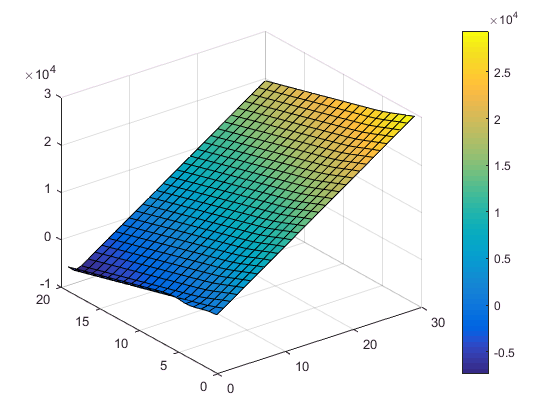

surf(Y,X,M)
colorbar

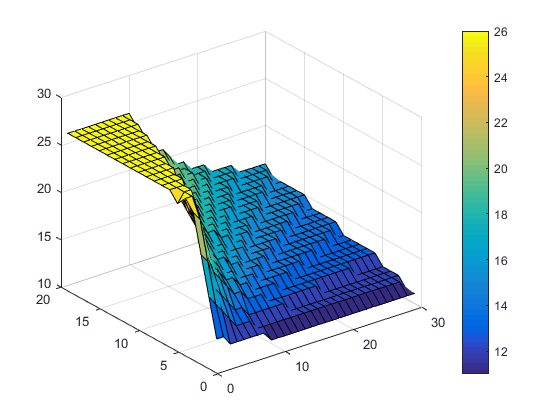

surf(Y,X,N)
colorbar